clc;
clear;

% Signal construction 
% 2.2.1
fs=512;

n1=0:511;
n2=512:1023;
n=[n1 n2];

x1n1=2*sin(20*pi*n1/fs)+sin(80*pi*n1/fs);
x1n2=0.5*sin(40*pi*n2/fs)+sin(60*pi*n2/fs);
x1n=[x1n1 x1n2];

x2n=zeros(1,1024);
x2n(1:64)=1;

x2n(129:512)=-1;
x2n(193:256)=2;
x2n(513:704)=3;
x2n(705:960)=1;
rng(56);
y1=awgn(x1n,10,'measured');
y2=awgn(x2n,10,'measured');


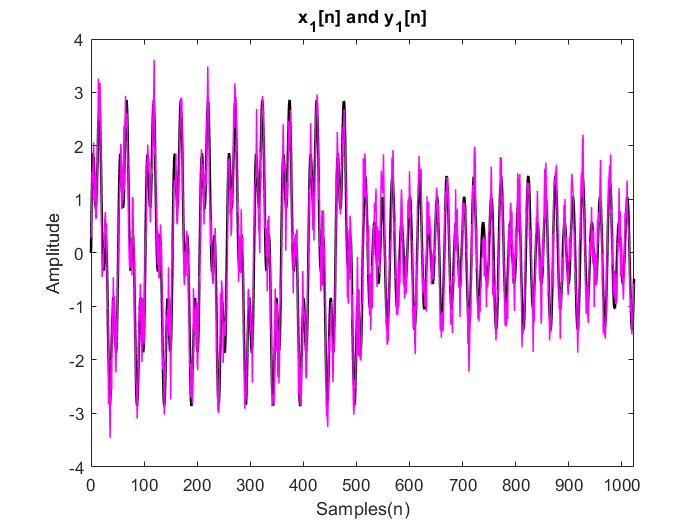


figure('Name','x_1[n] and y_1[n]');
plot(n,x1n,'k','LineWidth',1.5);
hold on;
plot(n,y1,'m','LineWidth',0.9);
hold off;
xlim([0 1023]);
xlabel('Samples(n)');
ylabel('Amplitude');
title('x_1[n] and y_1[n]')

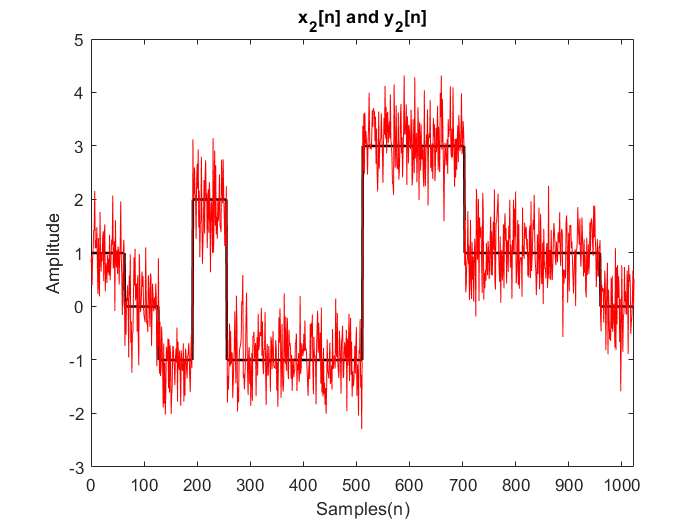


figure('Name','x_2[n] and y_2[n]');
plot(n,x2n,'k','LineWidth',1.5);
hold on;
plot(n,y2,'r');
hold off;
xlim([0 1023]);
xlabel('Samples(n)');
ylabel('Amplitude');
title('x_2[n] and y_2[n]');

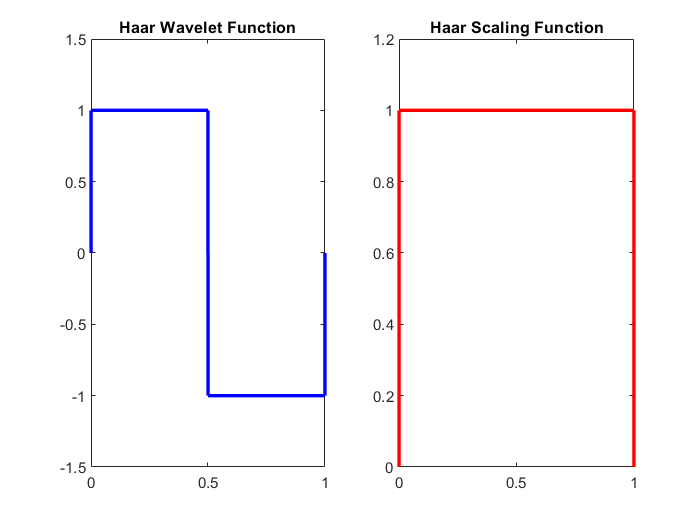

%% 2.2.2 

% Haar Wavelet
[phi_Haar, psi_Haar, val_Haar] = wavefun('haar', 12); 

figure ('Name','Haar Wavelet')
subplot(1,2,1);
plot(val_Haar, psi_Haar, 'b','LineWidth',2);
title('Haar Wavelet Function');
subplot(1,2,2);
plot(val_Haar, phi_Haar,'r','LineWidth',2);
title('Haar Scaling Function');

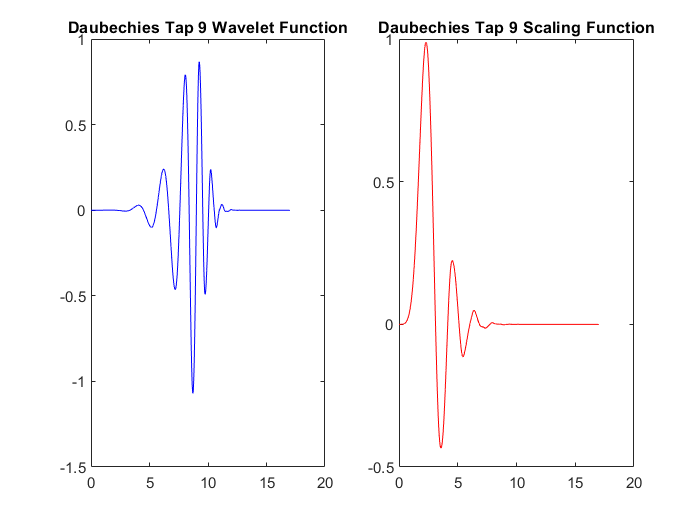


% Daubechies tap 9
[phi_Daube, psi_Daube, val_Daube] = wavefun('db9', 12); 

figure  ('Name','Daubechies tap 9 Wavelet')
subplot(1,2,1);
plot(val_Daube, psi_Daube,'b');
title('Daubechies Tap 9 Wavelet Function');
subplot(1,2,2);
plot(val_Daube, phi_Daube, 'r');
title('Daubechies Tap 9 Scaling Function');


%waveletAnalyzer

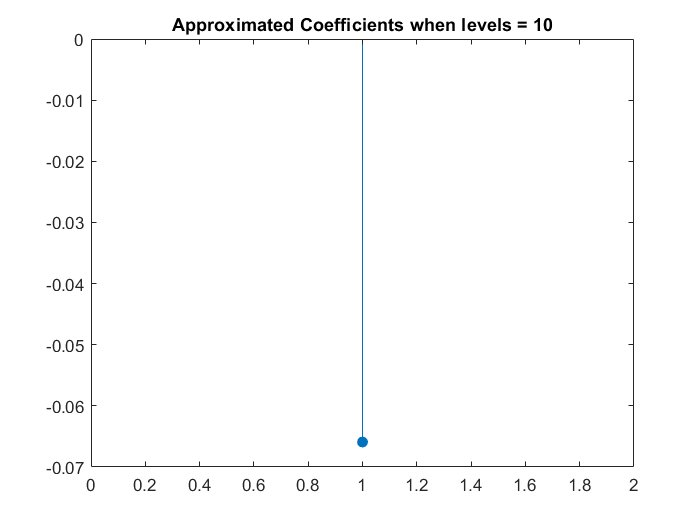

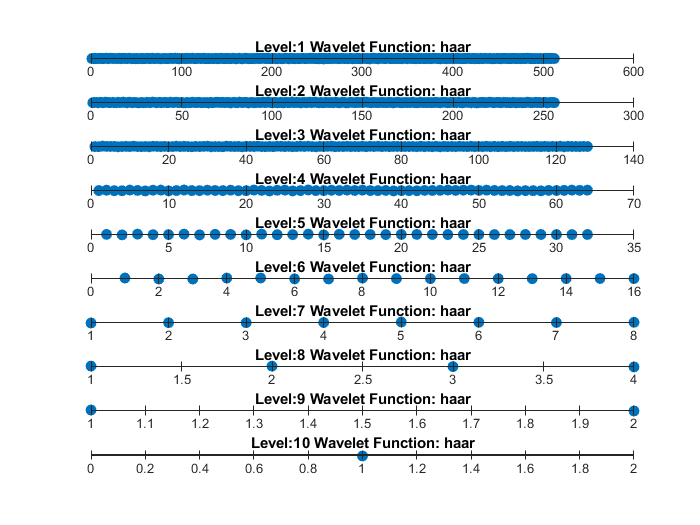

% 2.2.3
% x1[n] decomposition

[C1_h, L1] = wavedec(y1, 10, 'haar');
C1_h_A10 = appcoef(C1_h, L1, 'haar');
[C1_h_d1, C1_h_d2, C1_h_d3, C1_h_d4, C1_h_d5, C1_h_d6, C1_h_d7 ,C1_h_d8, C1_h_d9, C1_h_d10] = detcoef(C1_h, L1, 1:1:10);

[C1_db, L2] = wavedec(y1, 10, 'db9');
C1_db_A10 = appcoef(C1_db, L2, 'db9');
[C1_db_1, C1_db_2, C1_db_3, C1_db_4, C1_db_5, C1_db_6, C1_db_7 ,C1_db_8, C1_db_9, C1_db_10] = detcoef(C1_db, L2, 1:1:10);

% x2[n] decomposition
[C2_h, L3] = wavedec(y2, 10, 'haar');
C2_h_A10 = appcoef(C2_h, L3, 'haar');
[C2_h_1, C2_h_2, C2_h_3, C2_h_4, C2_h_5, C2_h_6, C2_h_7 ,C2_h_8, C2_h_9, C2_h_10] = detcoef(C2_h, L3, 1:1:10);

[C2_db, L4] = wavedec(y2, 10, 'db9');
C2_db_A10 = appcoef(C2_db, L4, 'db9');
[C2_db_1, C2_db_2, C2_db_3, C2_db_4, C2_db_5, C2_db_6, C2_db_7 ,C2_db_8, C2_db_9, C2_db_10] = detcoef(C2_db, L4, 1:1:10);

PlotDecomposedSignal(y1,'haar',10);

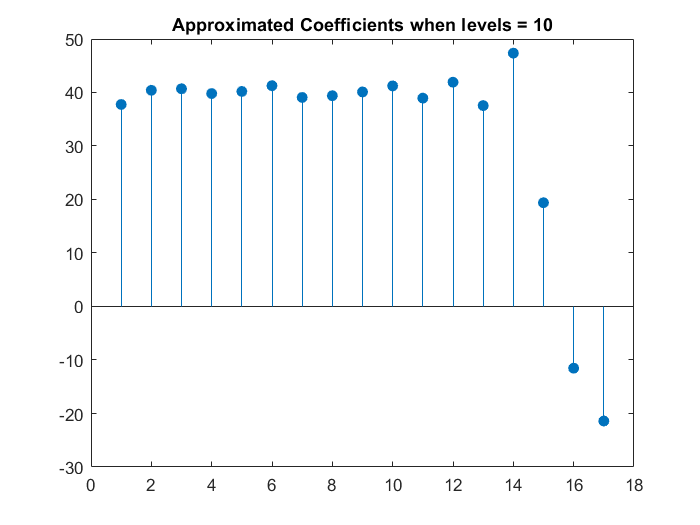

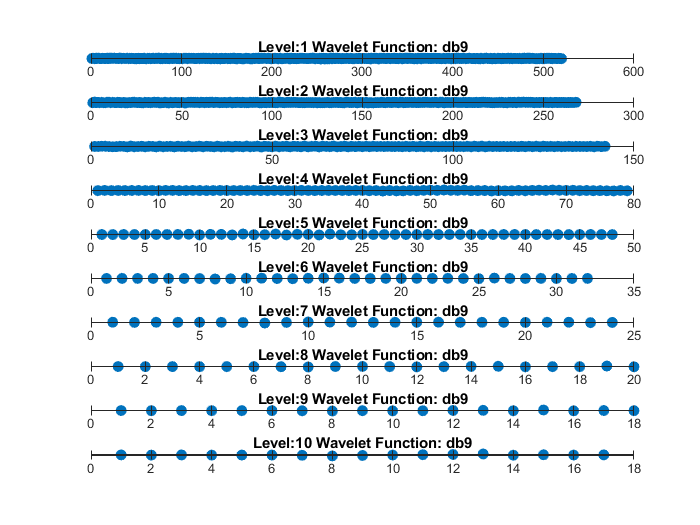

PlotDecomposedSignal(y1, 'db9', 10);

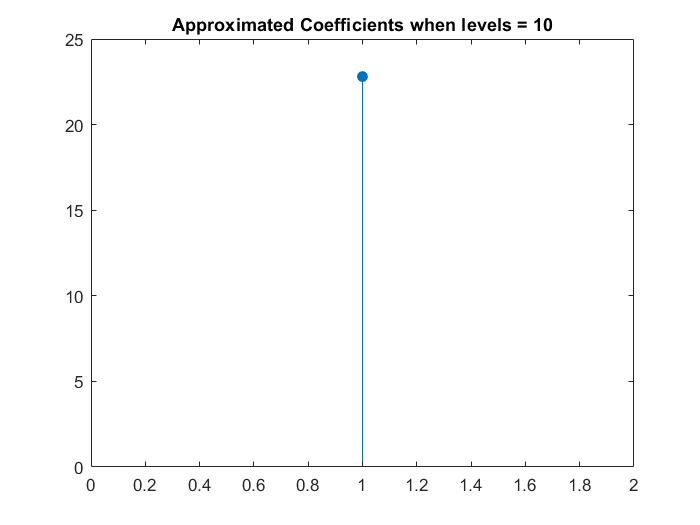

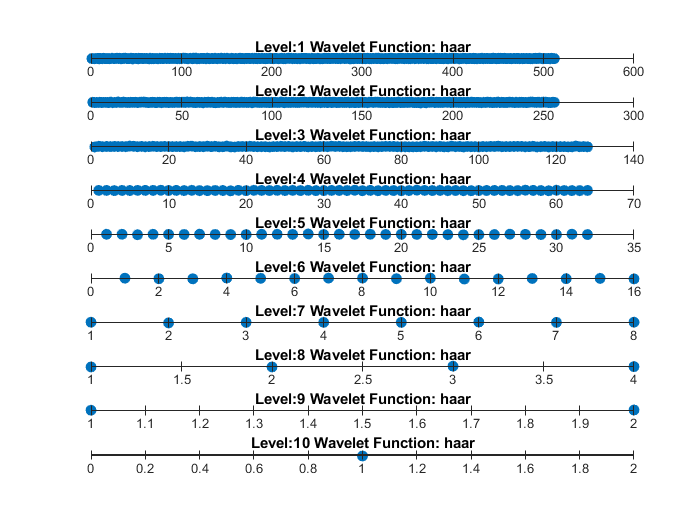

PlotDecomposedSignal(y2,'haar',10);

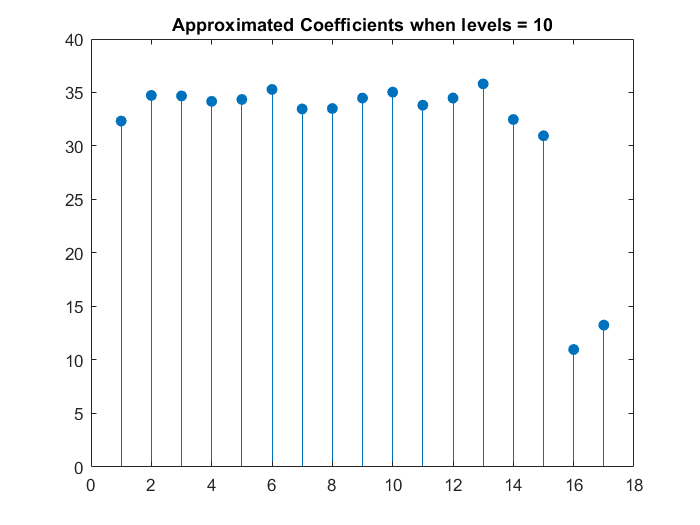

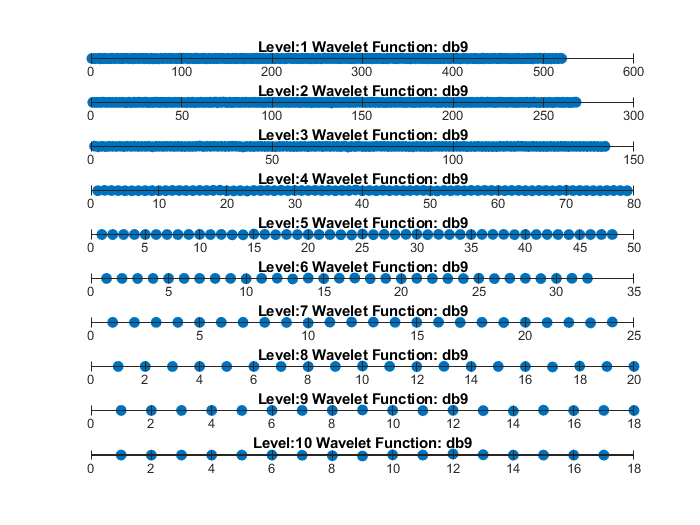

PlotDecomposedSignal(y2, 'db9', 10);

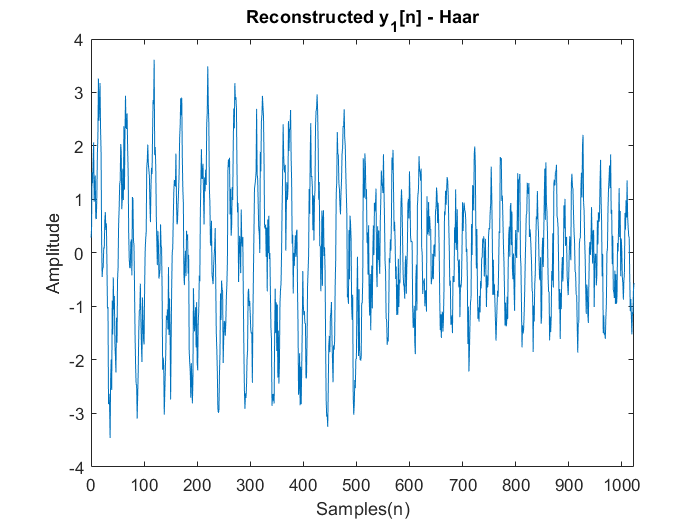


%% 2.2.4
% Reconstructing y1 - Haar

haar_A9_1 = idwt(C1_h_A10, C1_h_d10, 'haar');
haar_A8_1 = idwt(haar_A9_1, C1_h_d9, 'haar');
haar_A7_1 = idwt(haar_A8_1, C1_h_d8, 'haar');
haar_A6_1 = idwt(haar_A7_1, C1_h_d7, 'haar');
haar_A5_1 = idwt(haar_A6_1, C1_h_d6, 'haar');
haar_A4_1 = idwt(haar_A5_1, C1_h_d5, 'haar');
haar_A3_1 = idwt(haar_A4_1, C1_h_d4, 'haar');
haar_A2_1 = idwt(haar_A3_1, C1_h_d3, 'haar');
haar_A1_1 = idwt(haar_A2_1, C1_h_d2, 'haar');

y1_haar_recons = idwt(haar_A1_1, C1_h_d1, 'haar');

figure;
plot(n, y1_haar_recons);
title('Reconstructed y_1[n] - Haar');
xlabel('Samples(n)');
ylabel('Amplitude');
xlim([0,1023])

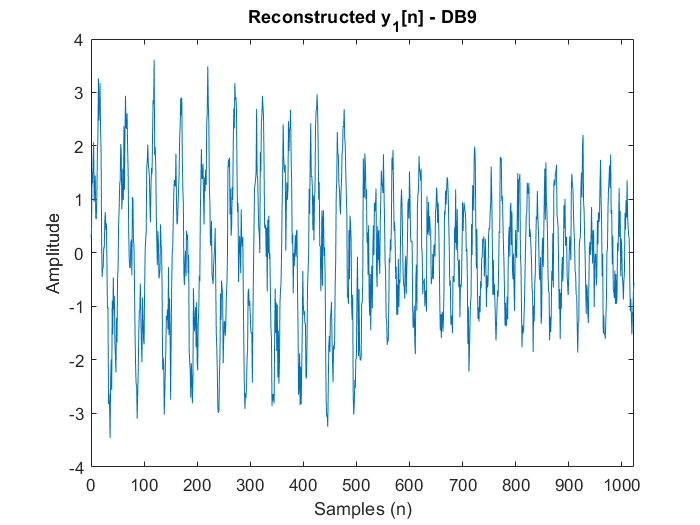


% Reconstructing y1 - DB9
db9_A9_1 = idwt(C1_db_A10, C1_db_10, 'db9');
db9_A8_1 = idwt(db9_A9_1, C1_db_9, 'db9');
db9_A7_1 = idwt(db9_A8_1, C1_db_8, 'db9');
db9_A6_1 = idwt(db9_A7_1, C1_db_7, 'db9');
db9_A5_1 = idwt(db9_A6_1, C1_db_6, 'db9');
db9_A4_1 = idwt(db9_A5_1, C1_db_5, 'db9');
db9_A3_1 = idwt(db9_A4_1(1:79), C1_db_4, 'db9');
db9_A2_1 = idwt(db9_A3_1, C1_db_3, 'db9');
db9_A1_1 = idwt(db9_A2_1, C1_db_2, 'db9');

y1_db_recons = idwt(db9_A1_1, C1_db_1, 'db9');

figure
plot(n, y1_db_recons);
title('Reconstructed y_1[n] - DB9');
xlabel('Samples (n)');
ylabel('Amplitude');
xlim([0,1023])

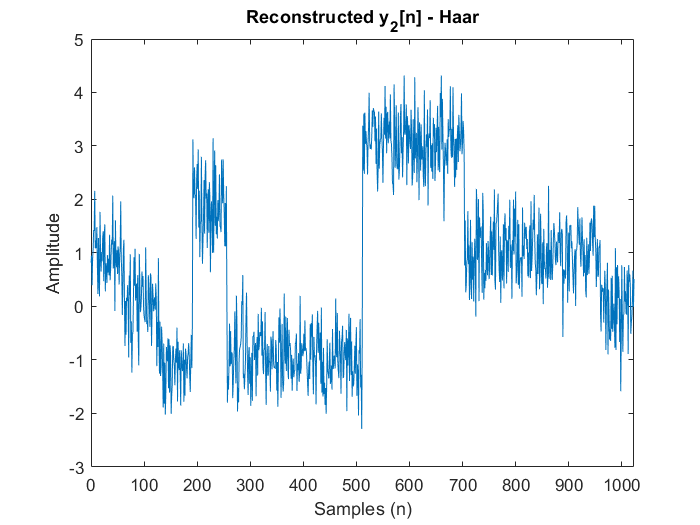


% Reconstructing y_2 - Haar
haar_A9_2 = idwt(C2_h_A10, C2_h_10, 'haar');
haar_A8_2 = idwt(haar_A9_2, C2_h_9, 'haar');
haar_A7_2 = idwt(haar_A8_2, C2_h_8, 'haar');
haar_A6_2 = idwt(haar_A7_2, C2_h_7, 'haar');
haar_A5_2 = idwt(haar_A6_2, C2_h_6, 'haar');
haar_A4_2 = idwt(haar_A5_2, C2_h_5, 'haar');
haar_A3_2 = idwt(haar_A4_2, C2_h_4, 'haar');
haar_A2_2 = idwt(haar_A3_2, C2_h_3, 'haar');
haar_A1_2 = idwt(haar_A2_2, C2_h_2, 'haar');

y2_haar_recons = idwt(haar_A1_2, C2_h_1, 'haar');

figure
plot(n, y2_haar_recons);
title('Reconstructed y_2[n] - Haar');
xlabel('Samples (n)');
ylabel('Amplitude');
xlim([0,1023])

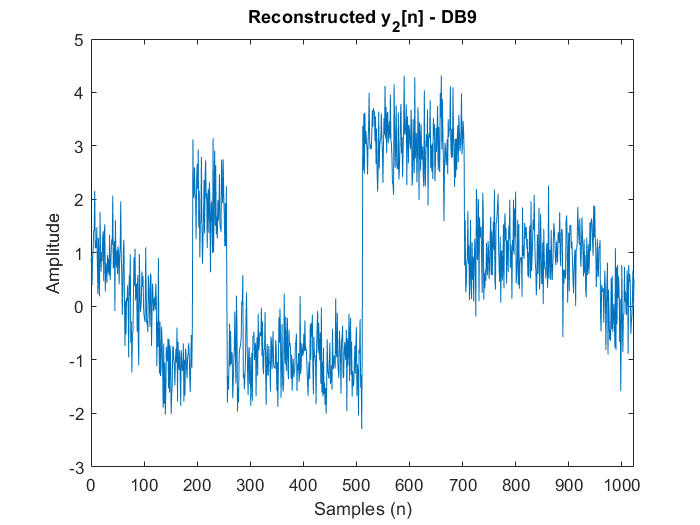


db9_A9_2 = idwt(C2_db_A10, C2_db_10, 'db9');
db9_A8_2 = idwt(db9_A9_2, C2_db_9, 'db9');
db9_A7_2 = idwt(db9_A8_2, C2_db_8, 'db9');
db9_A6_2 = idwt(db9_A7_2, C2_db_7, 'db9');
db9_A5_2 = idwt(db9_A6_2, C2_db_6, 'db9');
db9_A4_2 = idwt(db9_A5_2, C2_db_5, 'db9');
db9_A3_2 = idwt(db9_A4_2(1:79), C2_db_4, 'db9');
db9_A2_2 = idwt(db9_A3_2, C2_db_3, 'db9');
db9_A1_2 = idwt(db9_A2_2, C2_db_2, 'db9');

y2_db_recons = idwt(db9_A1_2, C2_db_1, 'db9');

figure
plot(n, y2_db_recons);
title('Reconstructed y_2[n] - DB9');
xlabel('Samples (n)');
ylabel('Amplitude');
xlim([0,1023])


% Comparing the Energies 

energy_y1 = sum(abs(y1).^2);
energy_y1_recons_haar = sum(abs(y1_haar_recons).^2);
energy_y1_recons_db9 = sum(abs(y1_db_recons).^2);

energy_y2 = sum(abs(y2).^2);
energy_y2_recons_haar = sum(abs(y2_haar_recons).^2);
energy_y2_recons_db9 = sum(abs(y2_db_recons).^2);

disp('Energy of y_1: '), disp(energy_y1)

Energy of y_1: 
   1.7641e+03



disp('Energy of Reconstructed y_1 - Haar: '), disp(energy_y1_recons_haar)

Energy of Reconstructed y_1 - Haar: 
   1.7641e+03



disp('Energy of Reconstructed y_1 - DB9: '), disp(energy_y1_recons_db9)

Energy of Reconstructed y_1 - DB9: 
   1.7641e+03




disp('Energy of y_2: '), disp(energy_y2)

Energy of y_2: 
   2.9646e+03



disp('Energy of Reconstructed y_2 - Haar: '), disp(energy_y2_recons_haar)

Energy of Reconstructed y_2 - Haar: 
   2.9646e+03



disp('Energy of Reconstructed y_2 - DB9: '), disp(energy_y2_recons_db9)

Energy of Reconstructed y_2 - DB9: 
   2.9646e+03



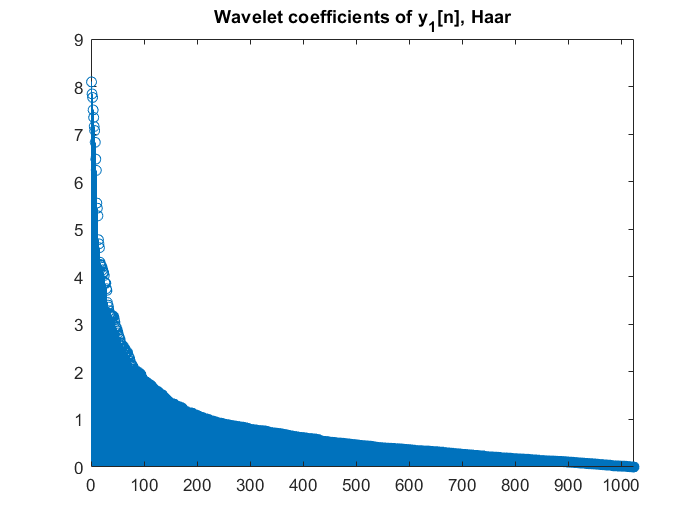


%% 2.3 Signal Denoising with DWT
% 2.3.1 

dord_C1h = sort(abs(C1_h(:)),'descend');
dord_C1db = sort(abs(C1_db(:)),'descend');
dord_C2h = sort(abs(C2_h(:)),'descend');
dord_C2db = sort(abs(C2_db(:)),'descend');

figure('Name',"Wavelet coefficients of y_1[n], Haar")
stem(dord_C1h);
xlim([0,length(dord_C1h)])
title("Wavelet coefficients of y_1[n], Haar");

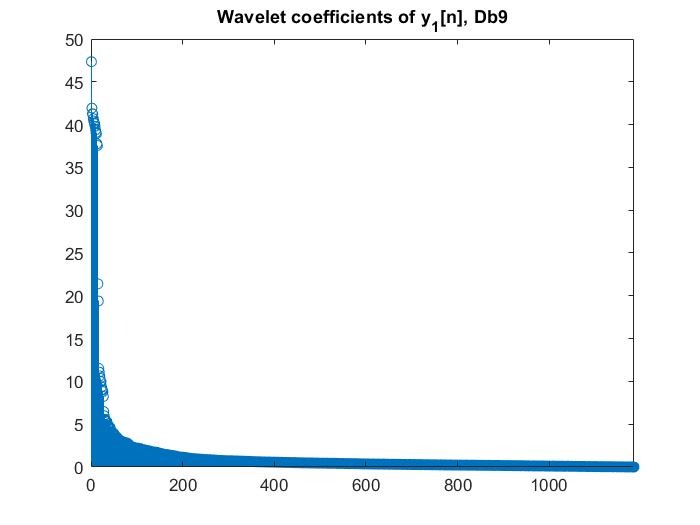


figure('Name',"Wavelet coefficients of y_1[n], Db9")
stem(dord_C1db );
xlim([0,length(dord_C1db)])
title("Wavelet coefficients of y_1[n], Db9");

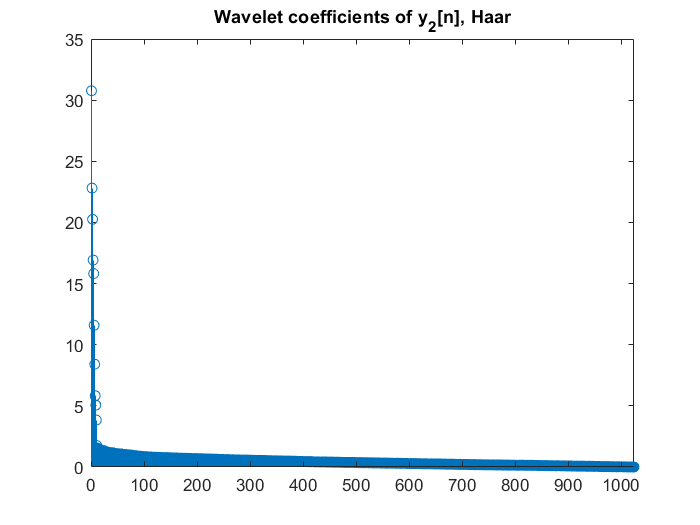


figure('Name',"Wavelet coefficients of y_2[n], Haar")
stem(dord_C2h);
xlim([0,length(dord_C2h)])
title("Wavelet coefficients of y_2[n], Haar");

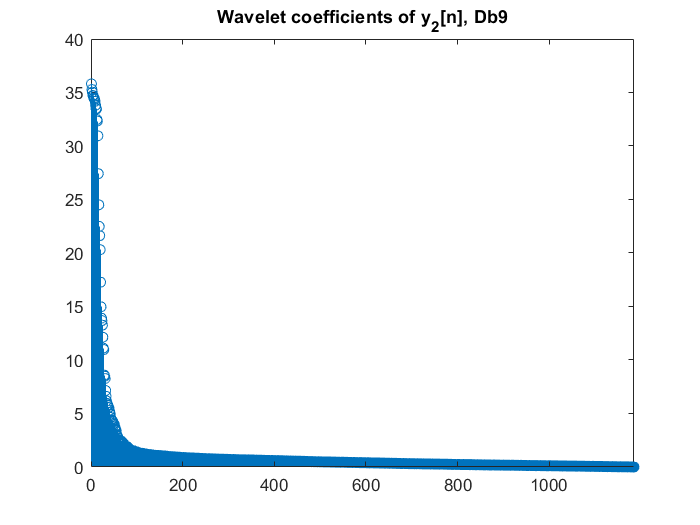


figure('Name',"Wavelet coefficients of y_2[n], Db9")
stem(dord_C2db);
xlim([0,length(dord_C2db)])
title("Wavelet coefficients of y_2[n], Db9");

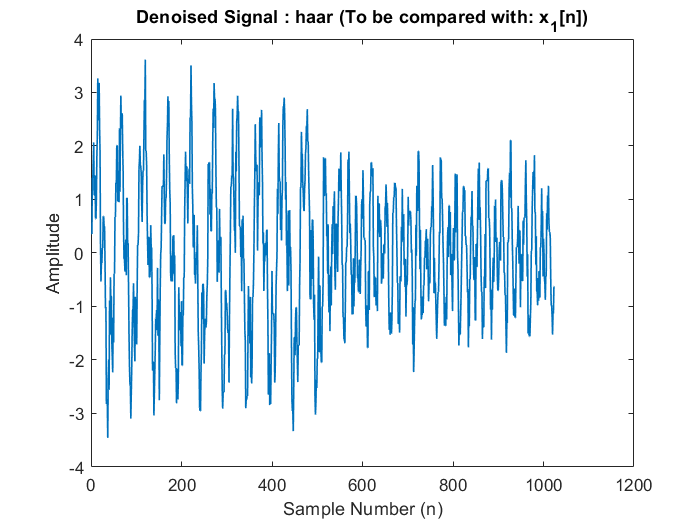

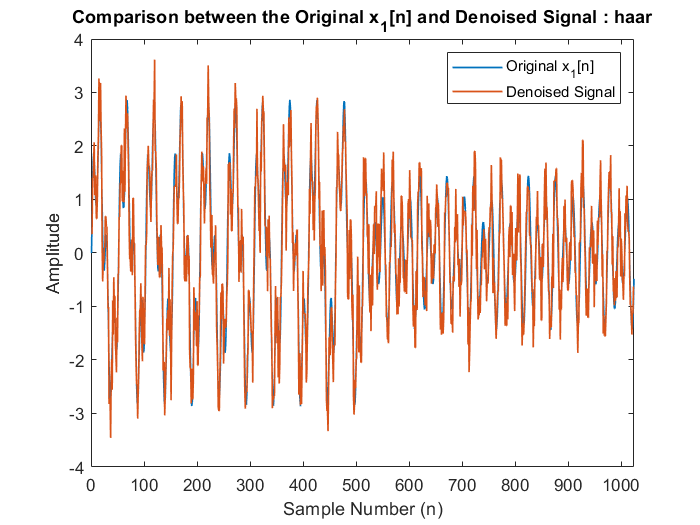


%% 2.3.2 \
%% 2.3.3 
%% 2.3.4 

% Setting the thresholds
thresh_for_y1_h = 0.2;
thresh_for_y1_db = 0.95;
thresh_for_y2_h = 2;
thresh_for_y2_db = 1.5;

% Denoising, Plotting and Calculating the RMSE
root_mean_sqr_err_haar_1 = denoiseDWTWavelet(C1_h,L1, x1n, 'haar',thresh_for_y1_h, 'x_1[n]');

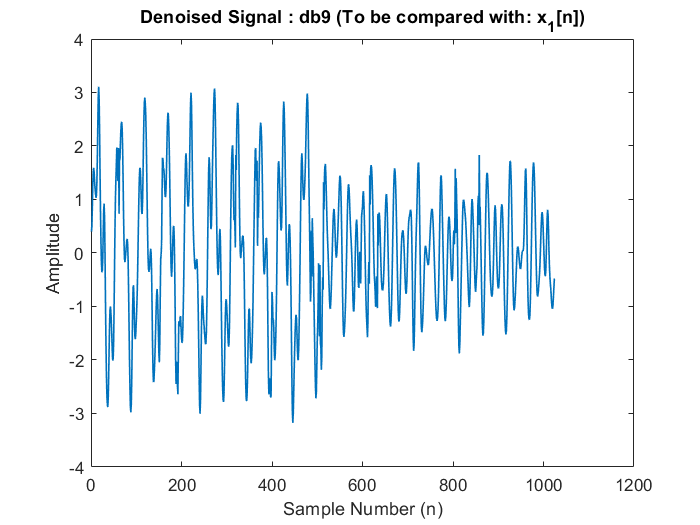

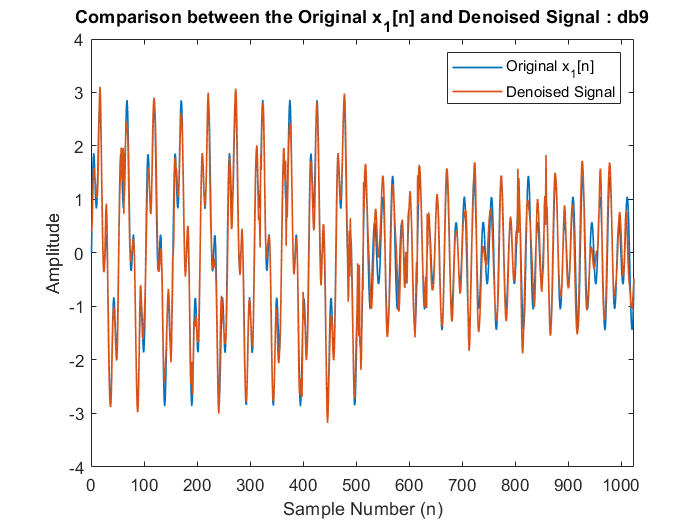

root_mean_sqr_err_db9_1 = denoiseDWTWavelet(C1_db,L2, x1n, 'db9',  thresh_for_y1_db, 'x_1[n]');

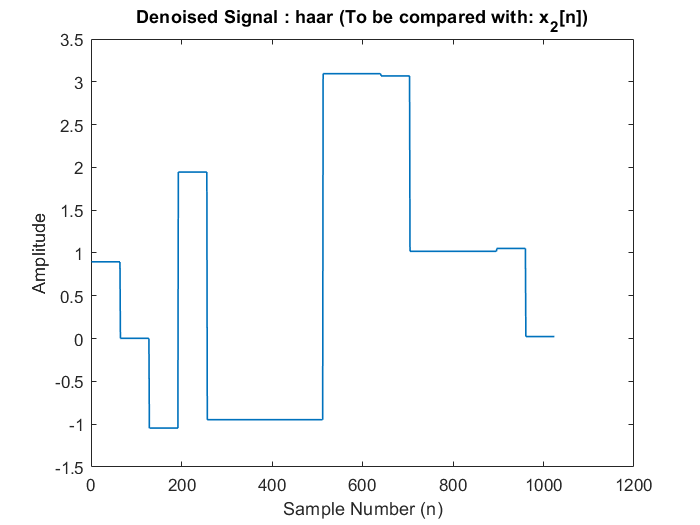

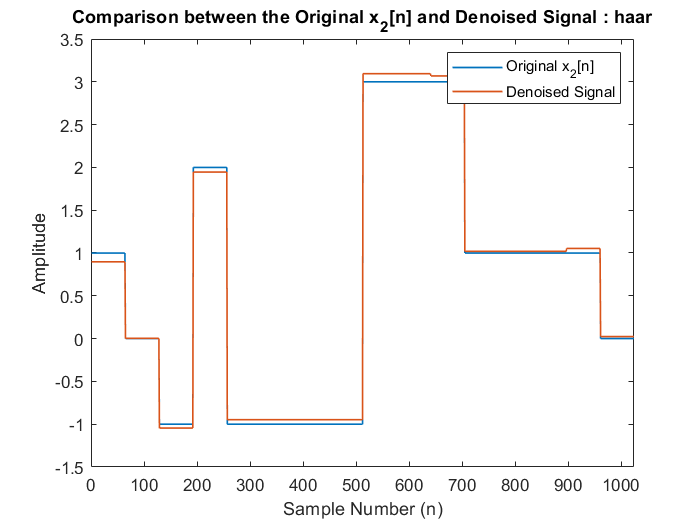

root_mean_sqr_err_haar_2 = denoiseDWTWavelet(C2_h,L3, x2n, 'haar', thresh_for_y2_h, 'x_2[n]');

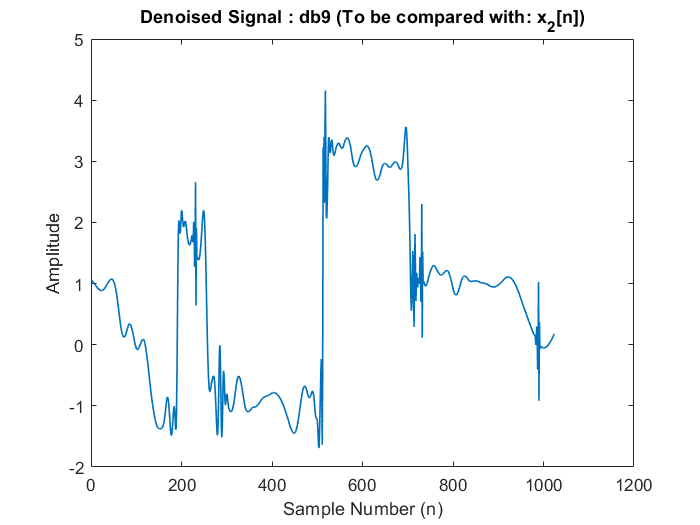

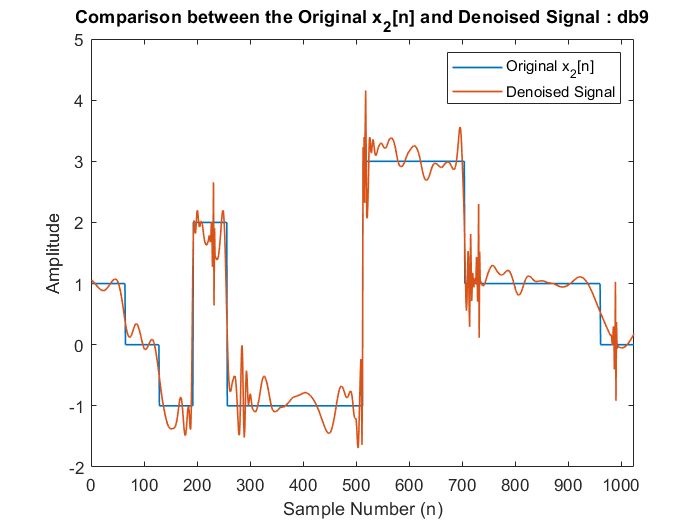

root_mean_sqr_err_db9_2 = denoiseDWTWavelet(C2_db,L4, x2n, 'db9', thresh_for_y2_db, 'x_2[n]');


disp('root mean square error of haar_1 '), disp(root_mean_sqr_err_haar_1)

root mean square error of haar_1 
    0.3991



disp('root mean square error of db9_1 '), disp(root_mean_sqr_err_db9_1)

root mean square error of db9_1 
    0.2875



disp('root mean square error of haar_2 '), disp(root_mean_sqr_err_haar_2)

root mean square error of haar_2 
    0.0580



disp('root mean square error of db9_2 '), disp(root_mean_sqr_err_db9_2)

root mean square error of db9_2 
    0.2797



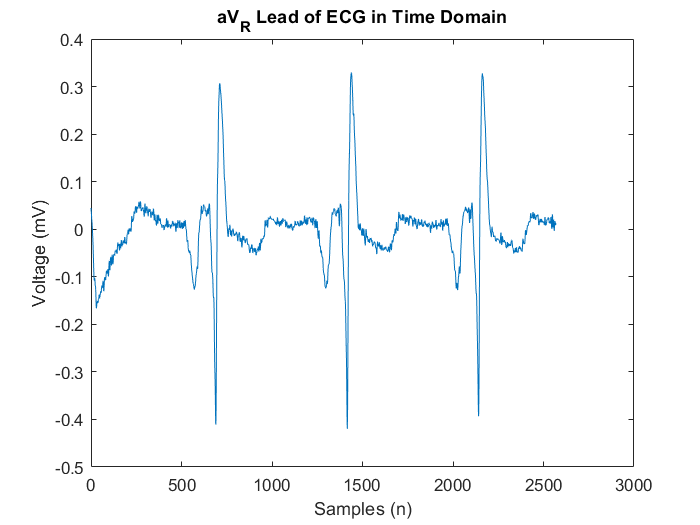


%% 2.3 Signal Compression with DWT
%% 2.3.1
%% 2.3.2 
%% 2.3.3 

ECGsig =  importdata('ECGsig.mat');      
duration = length(ECGsig);

fs = 257;
Ts = 1/fs;
n  = 0:1:(duration-1);

figure
plot(n, ECGsig);
title('aV_R Lead of ECG in Time Domain');
xlabel('Samples (n)');
ylabel('Voltage (mV)');

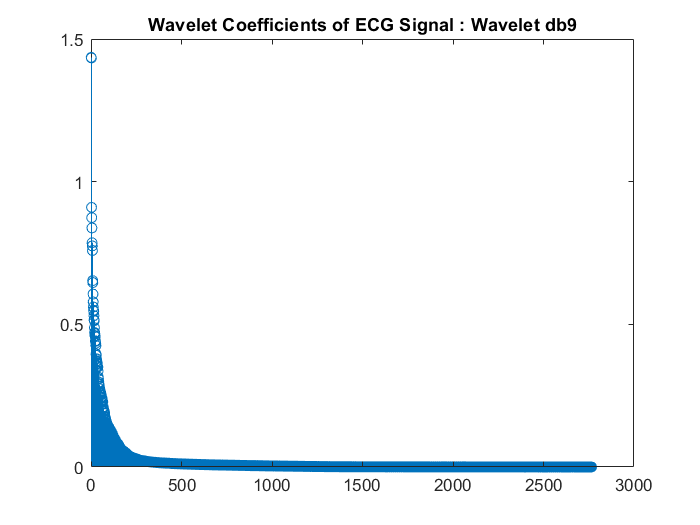

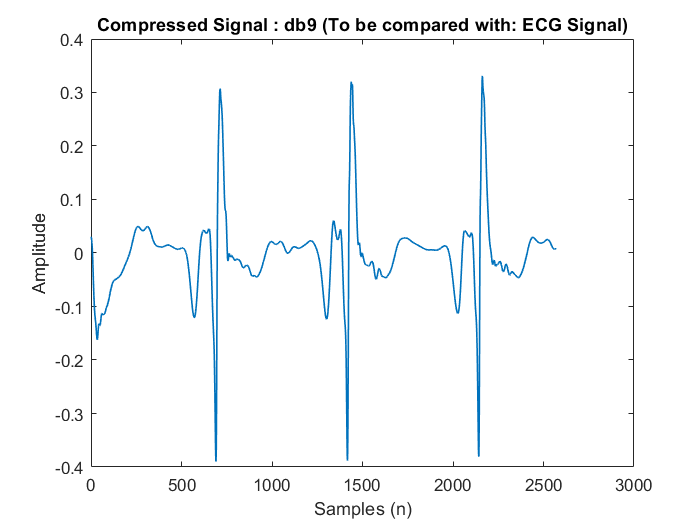

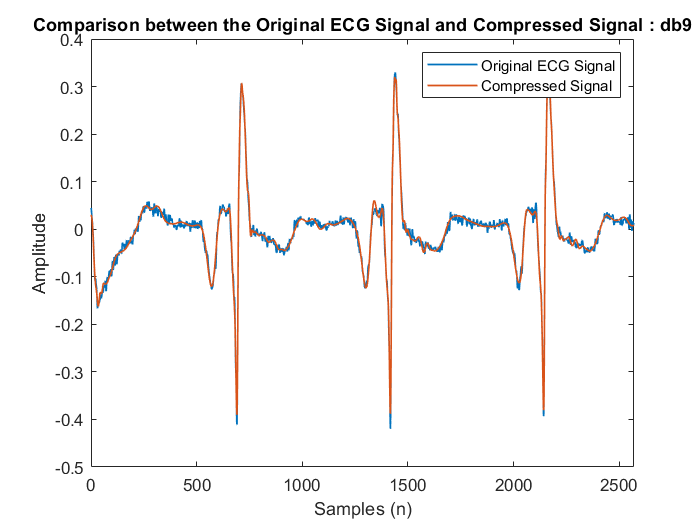


m = ceil(log2(duration));
 
[C1,l1]=wavedec(ECGsig,m,'db9');
[C2,l2]=wavedec(ECGsig,m,'haar');

[ratio_1, K1] = compressDWTECG(C1,l1, ECGsig, 'db9', 'ECG Signal'); 

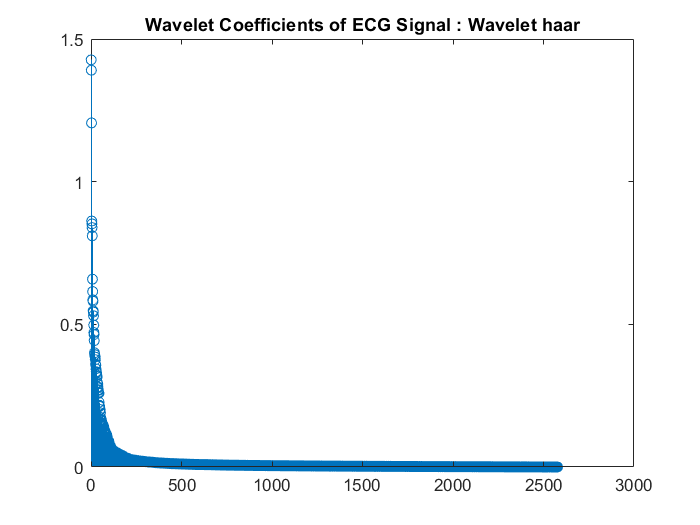

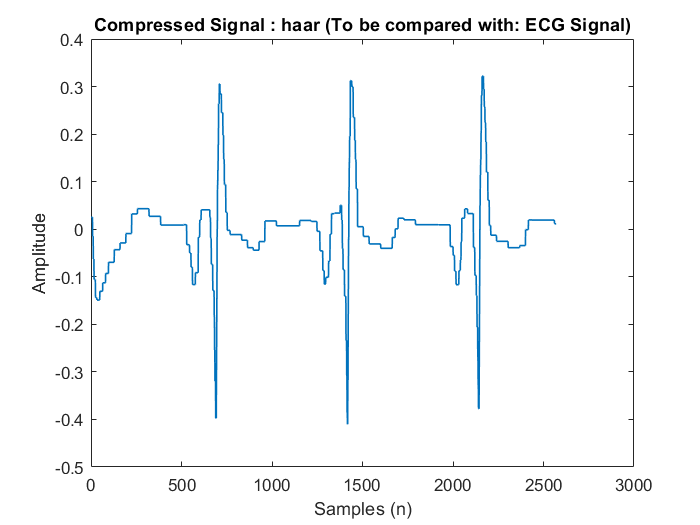

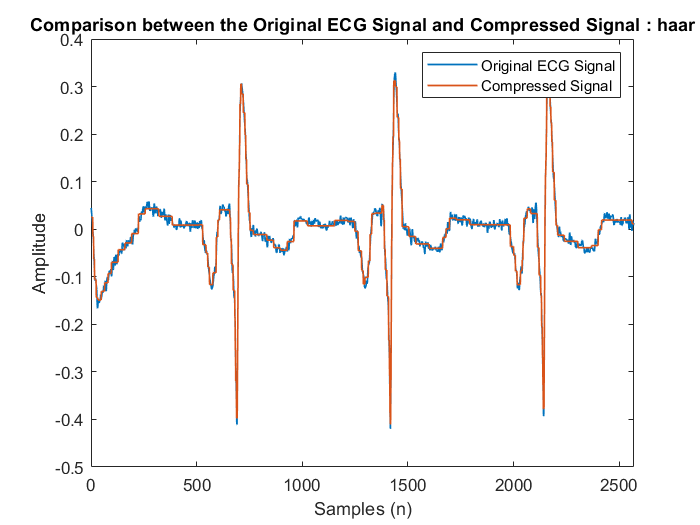

[ratio_2, K2] = compressDWTECG(C2,l2, ECGsig, 'haar','ECG Signal'); 


disp('compression ratio for db9 '), disp(ratio_1);

compression ratio for db9 
    0.0626



disp('compression ratio for haar'), disp(ratio_2);

compression ratio for haar
    0.0537

